# Example: Solving the emission circuit for a tree-like graph state

### State preparation:

Create the adjacency matrix `Gamma` of a simple connected graph:

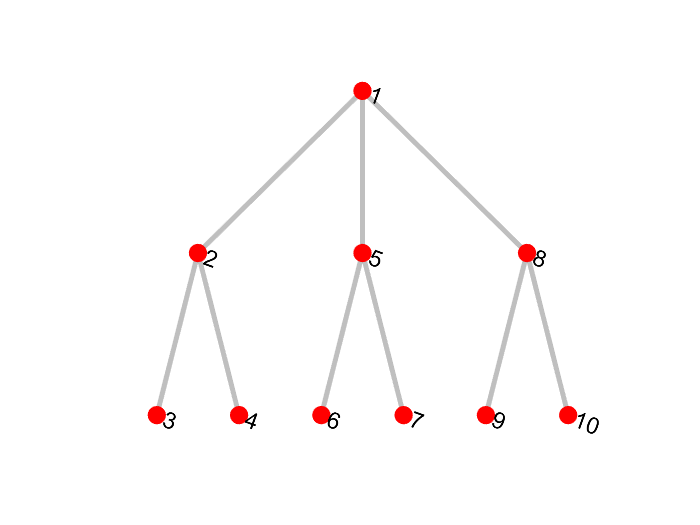

clear
filename = 'State1'; % filename
n = 10; % qubits number of target photonic state 
EdgesList = [1,2;1,5;1,8; 2,3;2,4; 5,6;5,7; 8,9;8,10]; % the list for edges
Gamma = full(sparse(EdgesList,fliplr(EdgesList),ones(size(EdgesList)),n,n));
figure;
plot(graph(Gamma),'MarkerSize',10,'NodeColor','r','EdgeColor',0.5*[1,1,1], ...
    'LineWidth',3,'NodeFontSize',14);
axis off

Where Gamma cannot have zero row and column, which represents 'decoupled qubit'.

Create the stabilizer generator `Gen` in the following way:

Gen.Tableau = [eye(n),Gamma]; % Tableau matrix for generators:
Gen.SignVector = zeros(n,1); % vector that represent the signs in front of these generators: 0 for '+', 1 for '-'.

Where` tableau` is way of representing Pauli matrices $\{I,X,Y,Z\}$ in $\mathbb{F}_2^2$ as $(0,0),\;
(1,0),\;
(1,1),\;
(0,1)$, with multiplication being replaced by addition, and phases are ignored, which are stored in `SignVector` instead. For example, for bell state $|\Psi^+\rangle$, the generators can be $g_1 = X_1X_2, g_2 = -Z_1Z_2$, then

`Gen.Tableau = [1,1,0,0;`

`               0,0,1,1];`

`Gen.SignVector = [0;1];`

So we can replace `Gen` by any pure stabilizer state. Use following code to load logical $|-\rangle_L$ state of Shor code from the root directory:

% load('ShorCode_x1.mat','Gen');

### Circuit solver:

Solve the circuit with `Gen` :

[Operation,InvOperation,Stat] = CircuitSolver(Gen);

	** The protocol is SOLVED correctly! **


where

- `Operation` records the data of $\{U_{e,j},U_{p,j},\eta_j,\mu_j,W_j,W_0\}$operations.

- `InvOperation` is the same operation set as `Operation` but with reversed unitaries. For instance: $P\to P^{-1}  = PZ$

- `Stat` is other data like height function, single qubit gates number, two-qubit gates number *et al*.

- "`SOLVED correctly`" means all of the generators has reduced to $+Z_i$.

The inside mechanism of CircuitSolver is displayed in `FlowChartMaker.mlx `in the root directory.

### Result Verification:

Verify if the output of `CircuitSolver` gives the correct state in normal time order, using stabilizer formalism.

[G_f_recover, G_Phi_recover] = ProtocolExecutor(InvOperation,Stat.EmittersNumber,Stat.PhotonsNumber); 
Equivalence = GeneratorsEquivalence(Gen,G_Phi_recover) % check the equivalence of Tableaus and SignVectors

Equivalence = struct with fields:
       Overall: 1
       Tableau: 1
    SignVector: 1


where

- `G_f_recover` is the final outcomes stabilizer generators of "photons + emitters" system.

- `G_Phi_recover` is the final outcomes stabilizer generators of of photons only.

### Display the circuit:

Print the $\mathrm{TeX}$ codes in a `quantikz_filename.txt` file for [quantikz](https://www.ctan.org/pkg/quantikz), which displays an easy-to-read circuit with $\mathrm{TeX}$ compiler.

Operation2quantikz(Operation,Stat.PhotonsNumber,Stat.EmittersNumber,filename);

	** The quantikz code for latex has been saved as: quantikz_State1.txt ** 


When compiling $\mathrm{TeX}$, we need to load:

`\usepackage{tikz} `

`\usetikzlibrary{quantikz}`

in the $\mathrm{TeX}$ compiler. 

Caveat: when n > 100, the circuit display is dense, and the $\mathrm{TeX}$ compilation could be slow, one may want to display the circuit with raw text (less readable) by the following compromising approach, which converts and saves the circuit solution in `ProtocolReport_filename.txt`, by executing:

ProtocolPrinter(Operation,Stat,filename);



 	 *** The protocol has been saved as ProtocolReport_State1.txt  ***.
 


Plot the height function $h_p(x)$ for the target photonic state.

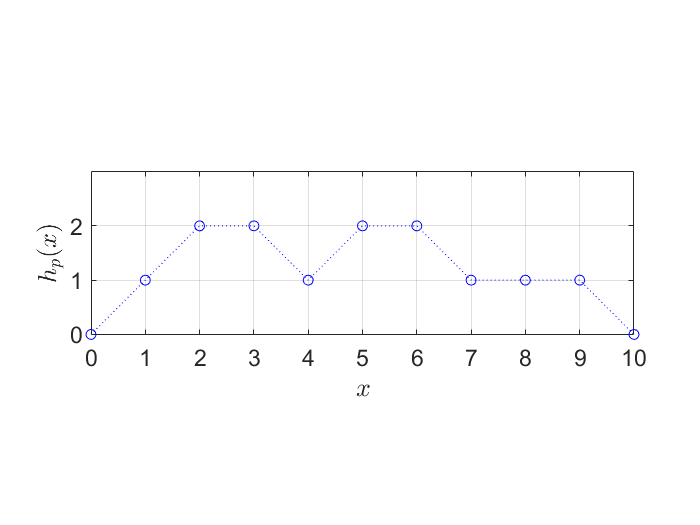

figure;
h = Stat.HeightFunc; % The height function of target photonic state.
plot(0:n,[0,h],':ob');
grid on
ax = gca;
xlabel('$x$','Interpreter','latex');
ylabel('$h_p(x)$','Interpreter','latex');
set(ax,'XTick',unique( round(ax.XTick)),'YTick',unique( round(ax.YTick) ), ...
    'XLim',[0,n],'YLim',[0,max(h)+1],'FontSize',14)
daspect([1,1,1]);

Where h is also accessible directly through:

% h = heightfunc(Gen.Tableau,'pure');